# Transfer Learning with Resnet 50

We re-use resnet 50 in an matlab example and mammogram dataset

clc, close all, clear all;

## Load Data

% unzip('MerchData.zip');
% imds = imageDatastore('MerchData','IncludeSubfolders',true,'LabelSource','foldernames');
imds = imageDatastore("data_roi_single_3/",'IncludeSubfolders',true,'LabelSource','foldernames');
% imds.ReadFcn = @(loc)imresize(imread(loc),[224,224,3]);
[imdsTrain,imdsValidation] = splitEachLabel(imds,0.8,'randomized');

## Display Random Images from dataset

This code displays images from **training dataset **

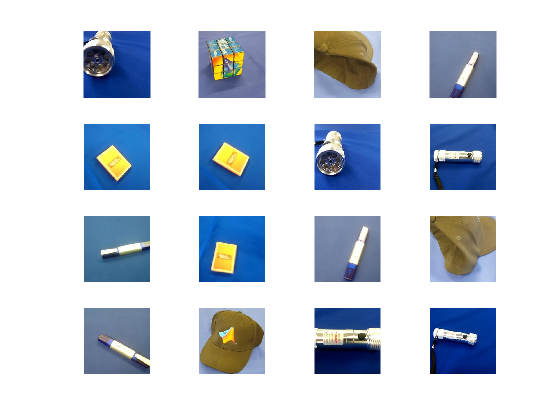

numTrainImages = numel(imdsTrain.Labels);
idx = randperm(numTrainImages,16);
figure
for i = 1:16
    subplot(4,4,i)
    I = readimage(imdsTrain,idx(i));
    imshow(I)
end

## Load Pretrained Network

net = resnet50;
% analyzeNetwork(net);

## Replace Final Layers

To learn faster in the new layers than in the transferred layers, increase the learning rate factors of the fully connected layer

numClasses = numel(categories(imdsTrain.Labels));
lgraph = layerGraph(net);

newFCLayer = fullyConnectedLayer(numClasses,'Name','new_fc','WeightLearnRateFactor',10,'BiasLearnRateFactor',10);
lgraph = replaceLayer(lgraph,'fc1000',newFCLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,'ClassificationLayer_fc1000',newClassLayer);

## Train Network

The network requires input images of size 224-by-224-by-3, but the images in the image datastore have different sizes. **Use an augmented image datastore to automatically resize the training images. **You can also use an `imageDataAugmenter`** to specify additional augmentation operations to perform on the training image**s to help prevent the network from overfitting.

inputSize = net.Layers(1).InputSize;
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain);
augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

### Training options:

Change execution environment to auto or parallel to to use CPU processing

For gpu processing use gpu or multi-gpu

options = trainingOptions('sgdm', ...
    'MiniBatchSize',10, ...
    'MaxEpochs',8, ...
    'InitialLearnRate',1e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',5, ...
    'ExecutionEnvironment', 'gpu', ...
    'Verbose',true, ...
    'Plots','training-progress');

Execute Training:

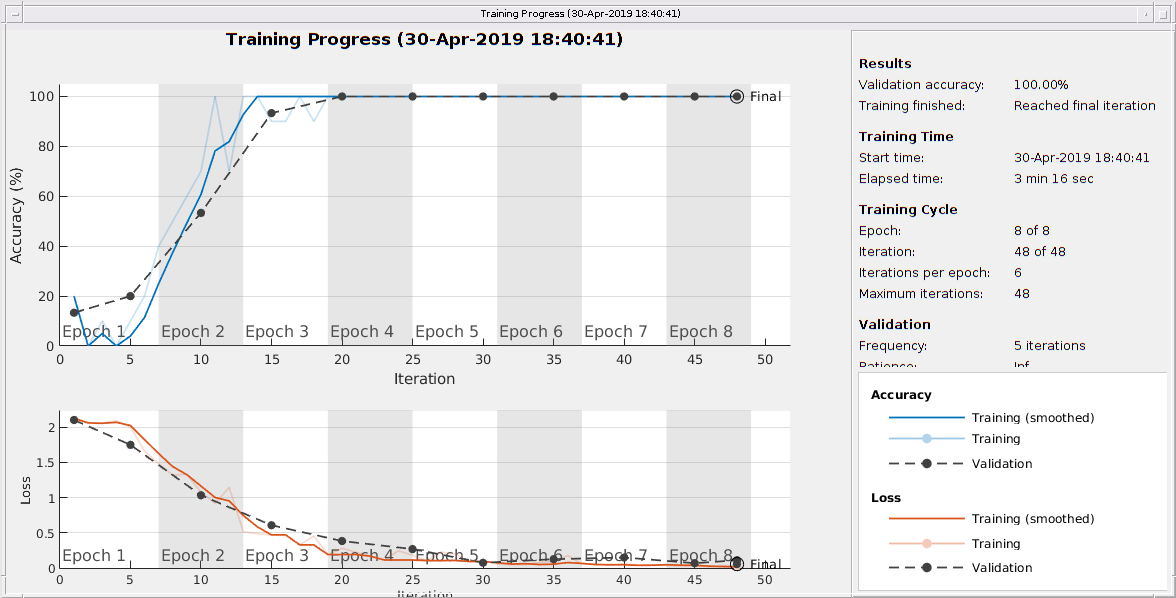

Initializing input data normalization.
|======================================================================================================================|
|  Epoch  |  Iteration  |  Time Elapsed  |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  |  Base Learning  |
|         |             |   (hh:mm:ss)   |   Accuracy   |   Accuracy   |     Loss     |     Loss     |      Rate       |
|======================================================================================================================|
|       1 |           1 |       00:00:08 |       20.00% |       13.33% |       2.1257 |       2.1024 |      1.0000e-04 |


|       1 |           5 |       00:00:24 |       10.00% |       20.00% |       2.0004 |       1.7495 |      1.0000e-04 |
|       2 |          10 |       00:00:42 |       70.00% |       53.33% |       1.0774 |       1.0342 |      1.0000e-04 |
|       3 |          15 |       00:01:00 |       90.00% |       93.33% |       0.4723 |       0.6090 |      1.0000e-04 |
|       4 |          20 |       00:01:18 |      100.00% |      100.00% |       0.2807 |       0.3848 |      1.0000e-04 |
|       5 |          25 |       00:01:37 |      100.00% |      100.00% |       0.1825 |       0.2707 |      1.0000e-04 |
|       5 |          30 |       00:01:57 |      100.00% |      100.00% |       0.1023 |       0.0764 |      1.0000e-04 |
|       6 |          35 |       00:02:16 |      100.00% |      100.00% |       0.0912 |       0.1272 |      1.0000e-04 |
|       7 |          40 |       00:02:37 |      100.00% |      100.00% |       0.0604 |       0.1512 |      1.0000e-04 |
|       8 |          45 |       

trainedNet = trainNetwork(augimdsTrain,lgraph,options);

## Classify Validation Images

Classify the validation images using the fine-tuned network, and calculate the classification accuracy.

YPred = classify(trainedNet,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 1